1.4(a)

题目要求利用所给的单位冲激函数和两倍的单位冲激函数证明系统y[n为非线性。

%构建出函数x1,x2,x3,y1，y2，y3
x = -3:1:3

x =     -3    -2    -1     0     1     2     3


x1 = [0 0 0 1 0 0 0 ]

x1 =      0     0     0     1     0     0     0


x2 = [0 0 0 2 0 0 0 ]

x2 =      0     0     0     2     0     0     0


x3 = x1 + x2

x3 =      0     0     0     3     0     0     0


y1 = sin(pi/2.*x1)

y1 =      0     0     0     1     0     0     0


y2 = sin(pi/2.*x2)

y2 = 1.0e-15 *

         0         0         0    0.1225         0         0         0


y3 = sin(pi/2.*x3)

y3 =      0     0     0    -1     0     0     0


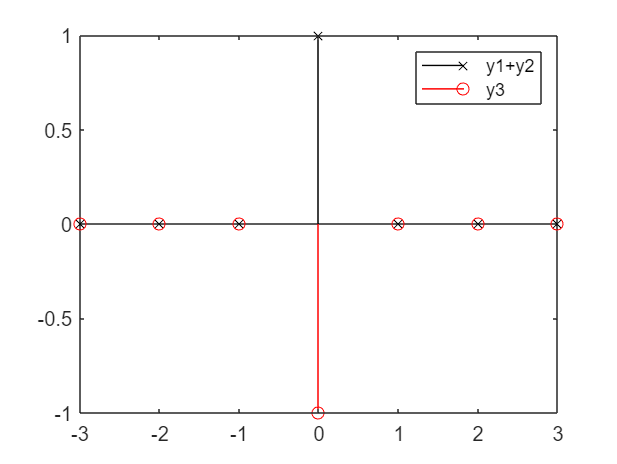

%画图比对y1+y2和y3是否一致
figure
stem(x,y1+y2,'k','x')
hold on
stem(x,y3,'r','o')
legend('y1+y2','y3')

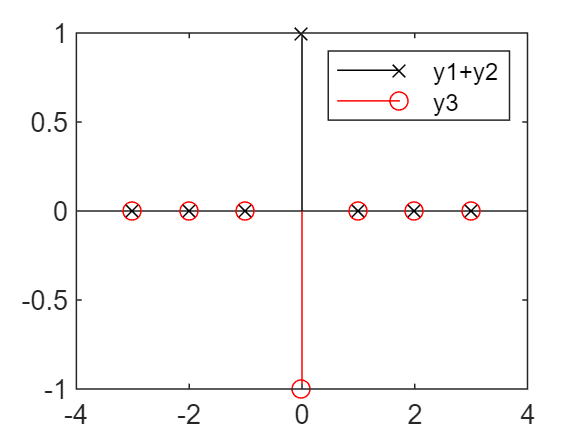

结论：y1+y2不等于y3，故系统为非线性。

(b) 通过x[n]=u[n]的例子证明y[n]=x[n]+x[n+1]为非因果函数

%构建x[n],y[n]
nx = -5:1:9

nx =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9


x1 = [0 0 0 0 0 ones(1,10)]

x1 =      0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


x2 = [0 0 0 0 ones(1,11)]

x2 =      0     0     0     0     1     1     1     1     1     1     1     1     1     1     1


y = x1 + x2

y =      0     0     0     0     1     2     2     2     2     2     2     2     2     2     2


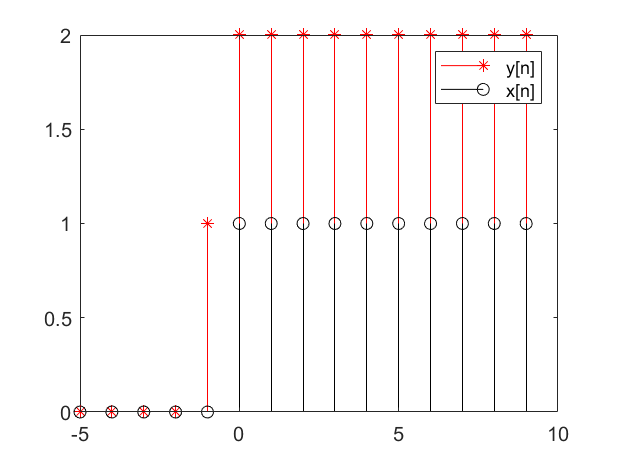

%绘制x[n]和y[n],对比图象
figure
stem(nx,y,'r','*')
hold on
stem(nx,x1,'k','o')
legend('y[n]','x[n]' )

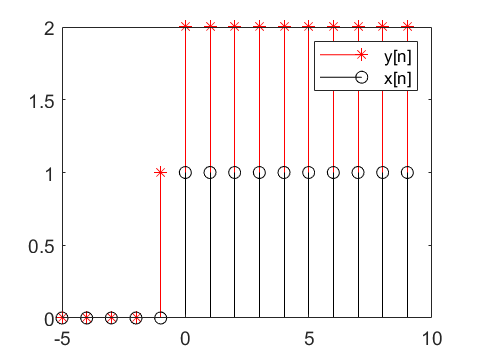

结论：n<=-1时，x[n]=0，而y[0]=1,显然由n>-1的x[n]所得，因此系统非线性。

（c)

题意：证明 y[n] = log(x[n]) 是不稳定的

%构造x[n]=0.5^n*u[n],y[n]
nx = 0:1:50

nx =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x = 0.5.^nx;
y = log(x)

y =          0   -0.6931   -1.3863   -2.0794   -2.7726   -3.4657   -4.1589   -4.8520   -5.5452   -6.2383   -6.9315   -7.6246   -8.3178   -9.0109   -9.7041  -10.3972  -11.0904  -11.7835  -12.4766  -13.1698  -13.8629  -14.5561  -15.2492  -15.9424  -16.6355  -17.3287  -18.0218  -18.7150  -19.4081  -20.1013  -20.7944  -21.4876  -22.1807  -22.8739  -23.5670  -24.2602  -24.9533  -25.6464  -26.3396  -27.0327  -27.7259  -28.4190  -29.1122  -29.8053  -30.4985  -31.1916  -31.8848  -32.5779  -33.2711  -33.9642


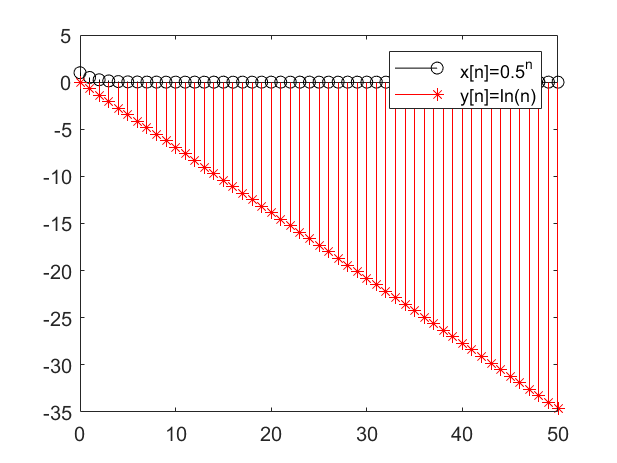

%作图
figure
stem(nx,x,'k')
hold on
stem(nx,y,'r','*')
legend('x[n]=0.5^n','y[n]=ln(n)')

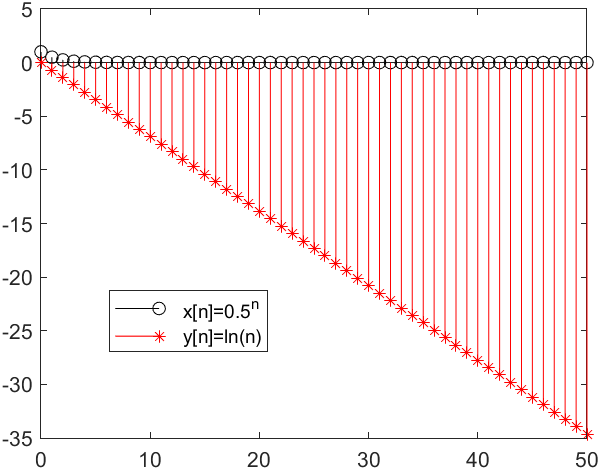

结论：当x[n]=0.5^n*u[n]时，x[n]有界，y[n]无界，系统不稳定。

(d)

题意：证明（c）中系统不可逆

%构造x1[n]=u[n],x2[n]=5u[n],y1[n],y2[n]
n = -3:1:3

n =     -3    -2    -1     0     1     2     3


x1 = [0 0 0 1 1 1 1]

x1 =      0     0     0     1     1     1     1


x2 = [0 0 0 5 5 5 5]

x2 =      0     0     0     5     5     5     5


y1 = sin(pi/2.*x1)

y1 =      0     0     0     1     1     1     1


y2 = sin(pi/2.*x2)

y2 =      0     0     0     1     1     1     1


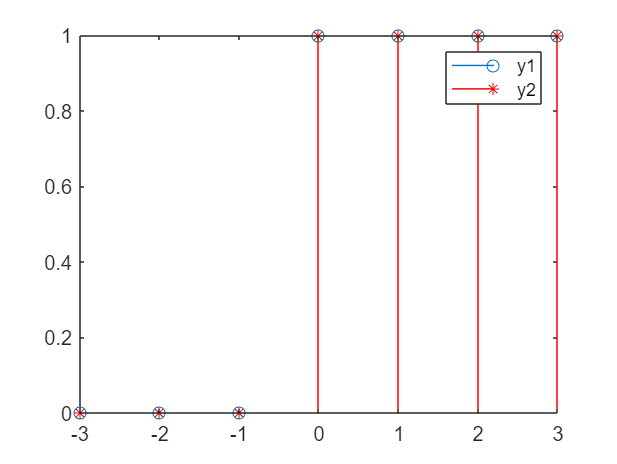

%绘图对比
figure
stem(n,y1)
hold on
stem(n,y2,'r','*')
legend('y1','y2')

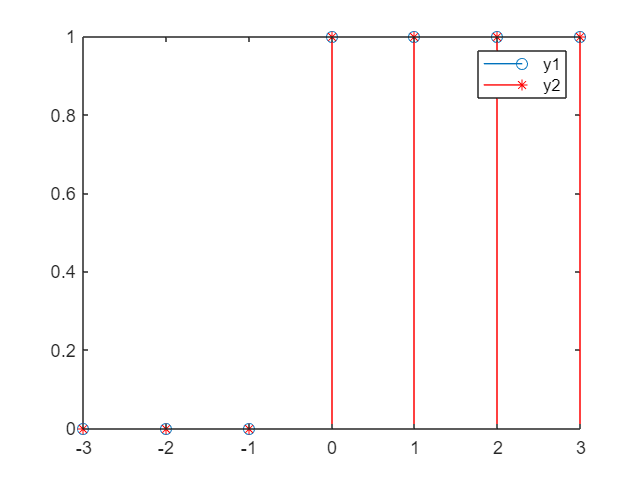

结论：当输入不同时，y[n]具有相同输出，因此系统不可逆。

（e)

阐述y[n]=x^3[n]是否线性、时不变、因果、稳定、可逆，如果不是，给出反例。

%证明非线性,假设x1[n]=n,x2[n]=2n,x3[n]=3n
n = -5:1:5

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


x1 = n

x1 =     -5    -4    -3    -2    -1     0     1     2     3     4     5


x2 = 2*n

x2 =    -10    -8    -6    -4    -2     0     2     4     6     8    10


x3 = 3*n

x3 =    -15   -12    -9    -6    -3     0     3     6     9    12    15


y1 = x1.^3

y1 =   -125   -64   -27    -8    -1     0     1     8    27    64   125


y2 = x2.^3

y2 =        -1000        -512        -216         -64          -8           0           8          64         216         512        1000


y3 = x3.^3

y3 =        -3375       -1728        -729        -216         -27           0          27         216         729        1728        3375


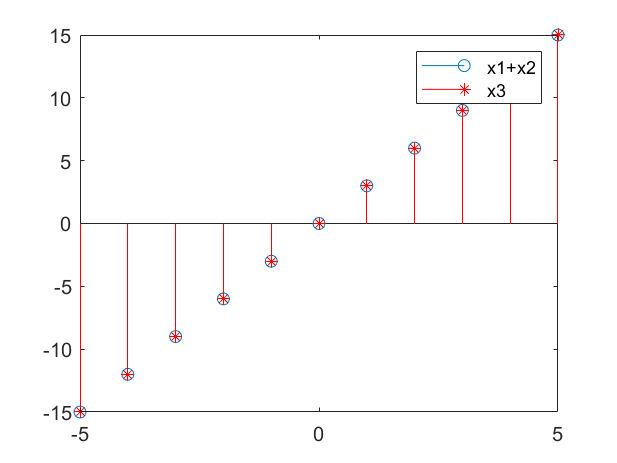

figure
stem(n,x1+x2)
hold on
stem(n,x3,'r','*')
legend('x1+x2','x3')

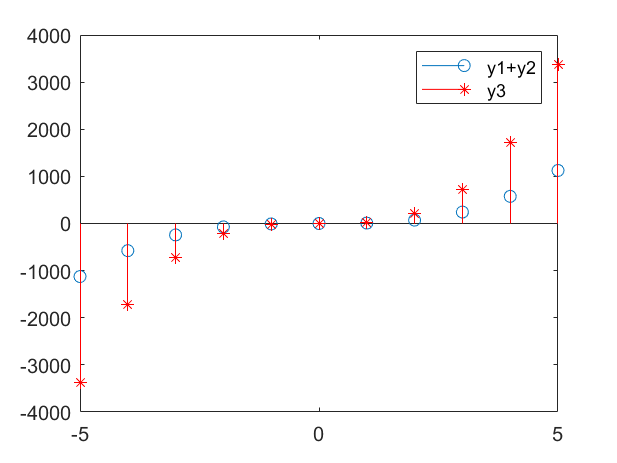

figure
stem(n,y1+y2)
hold on
stem(n,y3,'r','*')
legend('y1+y2','y3')

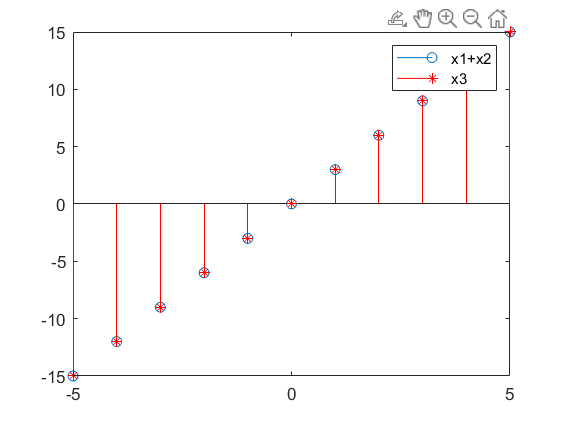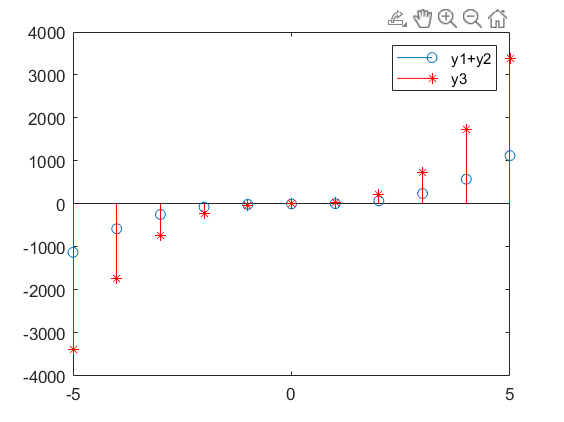

小结：x3[n]=x1[n]+x2[n]，但y3[n]不等于y2[n]+y1[n]，因此非线性。

结论：y[n]=x^3[n]时不变、因果、稳定、可逆；非线性。

（f）

阐述y[n]=n*x[n]是否线性、时不变、因果、稳定、可逆，如果不是，给出反例。

%证明时变，令输入为x[n]=n
clear
n = -5:1:5

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


System_f = @(x) x.*x

System_f = 包含以下值的 function_handle :
    @(x)x.*x


x1 = n

x1 =     -5    -4    -3    -2    -1     0     1     2     3     4     5


x2 = n-1

x2 =     -6    -5    -4    -3    -2    -1     0     1     2     3     4


y1 = System_f(x2)

y1 =     36    25    16     9     4     1     0     1     4     9    16


y2 = n.*x2

y2 =     30    20    12     6     2     0     0     2     6    12    20


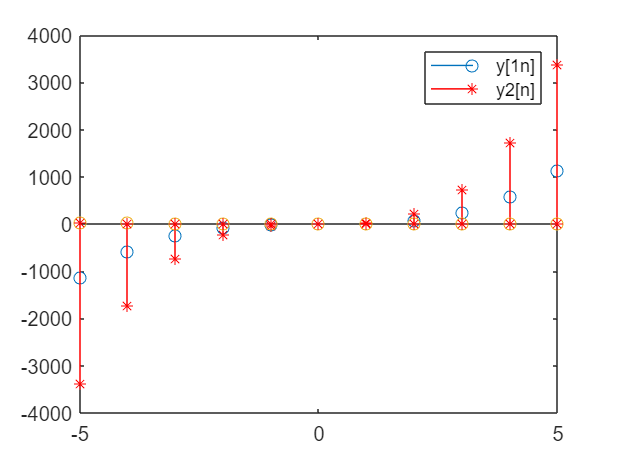

%画图对比y1，y2，证明时变
stem(n,y1)
hold on
stem(n,y2,'r','*')
legend('y[1n]','y2[n]')

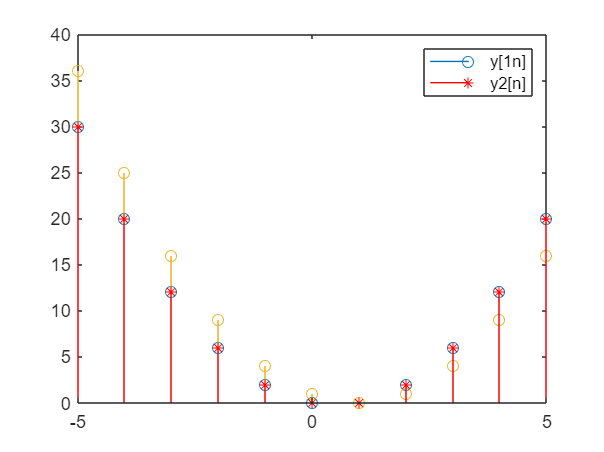

小结：y1是先时移后系统变换得来的，y2是先系统变换后时移所得，两者不同，系统时变。

%证明系统不稳定，令x[n]=u[n]
clear
n = -3:6

n =     -3    -2    -1     0     1     2     3     4     5     6


x = [0 0 0 1 1 1 1 1 1 1]

x =      0     0     0     1     1     1     1     1     1     1


System_f = @(nx) nx.*x

System_f = 包含以下值的 function_handle :
    @(nx)nx.*x


y = System_f(n)

y =      0     0     0     0     1     2     3     4     5     6


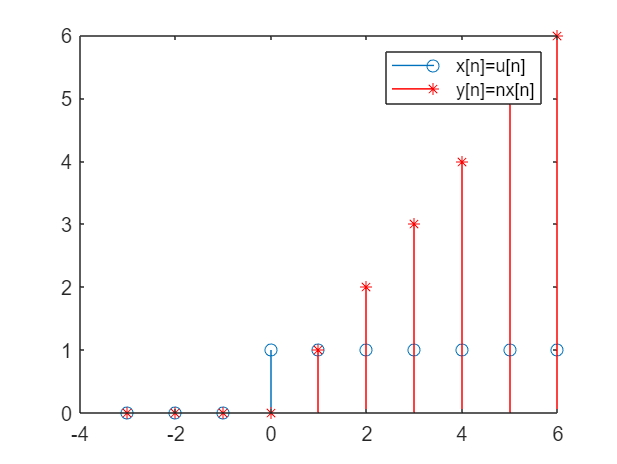

figure
stem(n,x),hold on,stem (n,y,'r','*')
legend('x[n]=u[n]','y[n]=nx[n]')

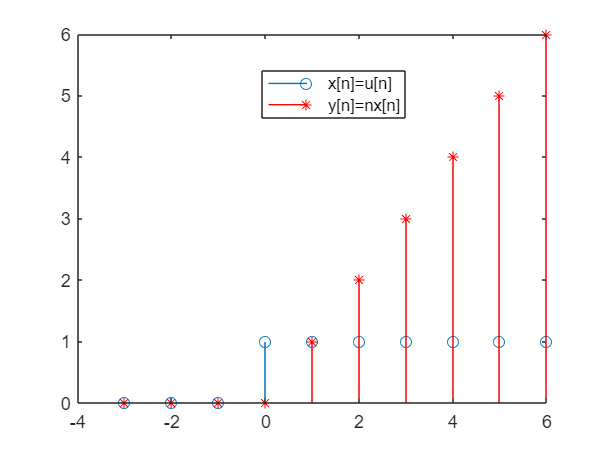

小结：当n为无穷时，y取值为无穷，无界，故系统不稳定。

%构造x1[n]=u[n],x2[n]=u[n-1],y1[n],y2[n]
n = -3:1:3

n =     -3    -2    -1     0     1     2     3


x1 = [0 0 0 1 1 1 1]

x1 =      0     0     0     1     1     1     1


x2 = [0 0 0 0 1 1 1]

x2 =      0     0     0     0     1     1     1


System_f = @(x) n.*x

System_f = 包含以下值的 function_handle :
    @(x)n.*x


y1 = System_f(x1)

y1 =      0     0     0     0     1     2     3


y2 = System_f(x2)

y2 =      0     0     0     0     1     2     3


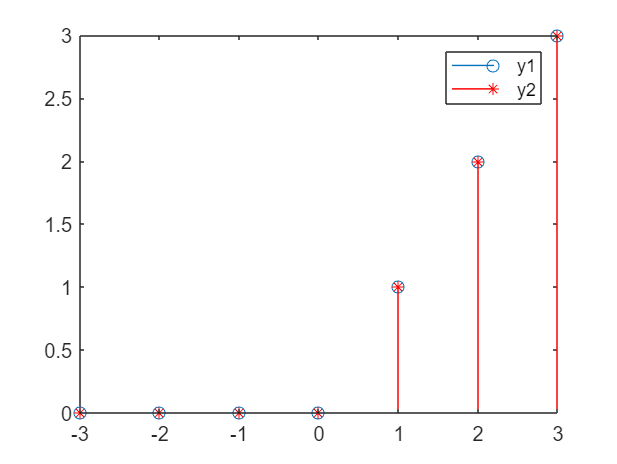

%绘图对比
figure
stem(n,y1)
hold on
stem(n,y2,'r','*')
legend('y1','y2')

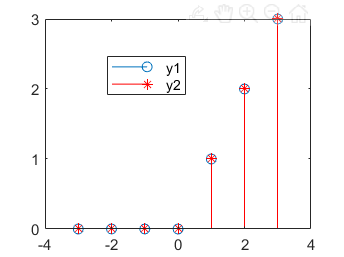

小结：输入不同，输出相同，系统不可逆。

结论：y[n]=x^3[n]线性、因果；不可逆、时变、不稳定。

（g）

阐述y[n]=x[2n]是否线性、时不变、因果、稳定、可逆，如果不是，给出反例。

%证明非因果性，令x[n] 为单位冲激函数向右时移2个单位
nx = -6:6

nx =     -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6


ny = -3:3

ny =     -3    -2    -1     0     1     2     3


x = [0 0 0 0 0 0 0 0 1 0 0 0 0]

x =      0     0     0     0     0     0     0     0     1     0     0     0     0


y = [0 0 0 0 1 0 0]

y =      0     0     0     0     1     0     0


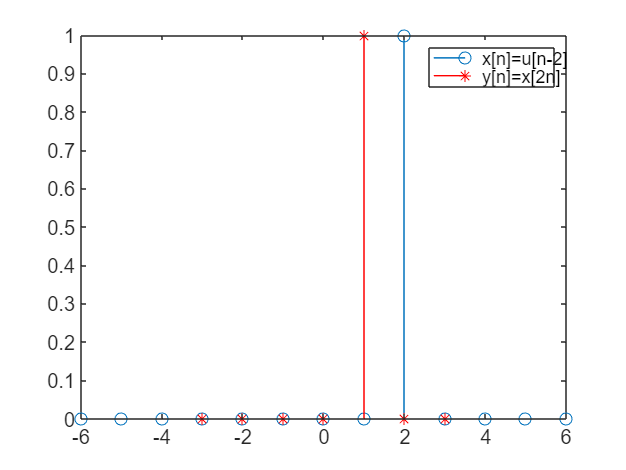

figure
stem(nx,x)
hold on
stem(ny,y,'r','*')
legend('x[n]=u[n-2]','y[n]=x[2n]')

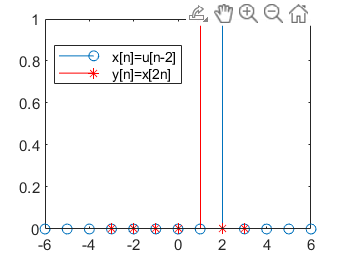

小结：令x[n] 为单位冲激函数向右时移2个单位，但此时n<2时，y[n]不都等于0，因此为非因果。

%证明时变，构造x[n]=cos(n)
clear
n = -6 : 6

n =     -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6


N = (-6 * 2) : (6 * 2)

N =    -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12


O = (-6 * 2 - 3) : (6 * 2 - 3)

O =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9


System_g = @(x) x(mod(N, 2) == 0)

System_g = 包含以下值的 function_handle :
    @(x)x(mod(N,2)==0)



x1 = cos(N)

x1 =     0.8439    0.0044   -0.8391   -0.9111   -0.1455    0.7539    0.9602    0.2837   -0.6536   -0.9900   -0.4161    0.5403    1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391    0.0044    0.8439


x2 = cos(O)

x2 =    -0.7597    0.1367    0.9074    0.8439    0.0044   -0.8391   -0.9111   -0.1455    0.7539    0.9602    0.2837   -0.6536   -0.9900   -0.4161    0.5403    1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111


y1 = System_g(x1)

y1 =     0.8439   -0.8391   -0.1455    0.9602   -0.6536   -0.4161    1.0000   -0.4161   -0.6536    0.9602   -0.1455   -0.8391    0.8439


y2 = System_g(x2)

y2 =    -0.7597    0.9074    0.0044   -0.9111    0.7539    0.2837   -0.9900    0.5403    0.5403   -0.9900    0.2837    0.7539   -0.9111


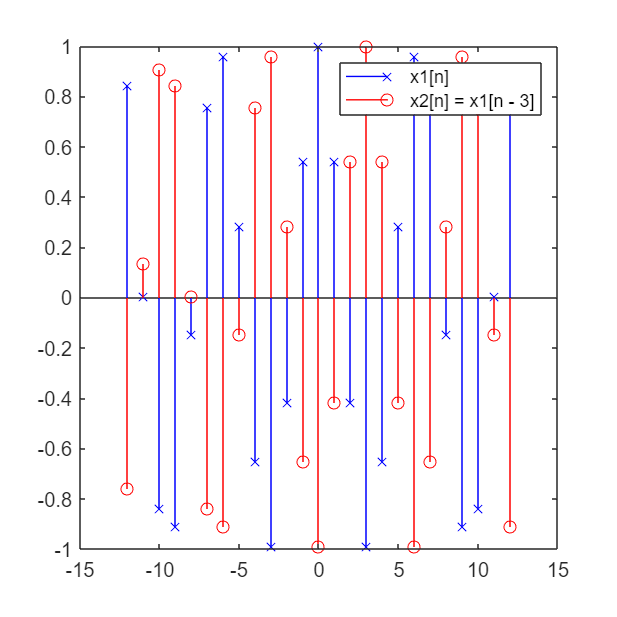

%绘图验证时移后的y1，y2是否相等
figure
set(gcf, 'position', [0 0 600 600]);
S = [-6 * 2 -3, 6 * 2 -3];
D = [-6 * 2, 6 * 2];
d = [-6, 6];

%subplot(3, 1, 1);
stem(N, x1, 'bx');
hold on
%subplot(3, 1, 2);
stem(N, x2, 'r');
legend('x1[n]','x2[n] = x1[n - 3]');

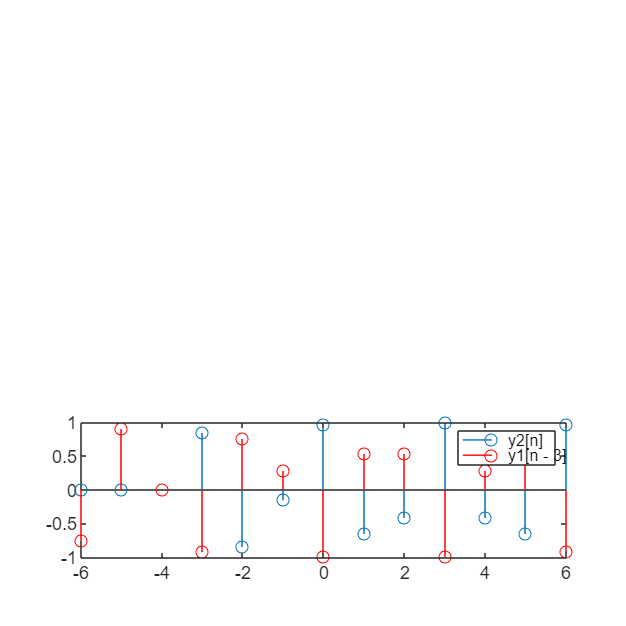


subplot(3, 1, 3);
stem(n, [zeros(1, abs(-3)), y1(1 : end -3)])
hold on
stem(n, y2, 'r');
legend('y2[n]', 'y1[n - 3]');

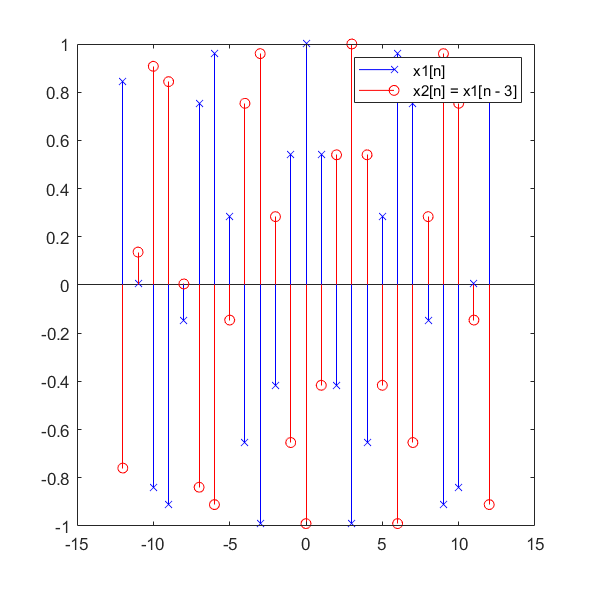

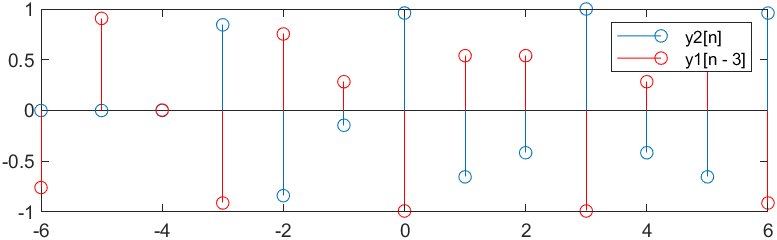

小结：对 x1[n] = cos(n) 进行时移，我们得到 x2[n]  = x1[n - 3]，经过变化， y2[n] ≠ y1[n - 3]，所以系统是时变的。

%证明不可逆,构造x1,x2
clear
n = -2 : 2

n =     -2    -1     0     1     2


N = -4 : 4

N = 1×9
    -4    -3    -2    -1     0     1     2     3     4


System_g = @(x) x(mod(N, 2) == 0)

System_g = 包含以下值的 function_handle :
    @(x)x(mod(N,2)==0)



x1 = [1 1 1 1 1 1 1 1 1]

x1 = 1×9
     1     1     1     1     1     1     1     1     1


y1 = System_g(x1)

y1 = 1×5
     1     1     1     1     1



x2 = [1 0 1 0 1 0 1 0 1]

x2 = 1×9
     1     0     1     0     1     0     1     0     1


y2 = System_g(x2)

y2 = 1×5
     1     1     1     1     1


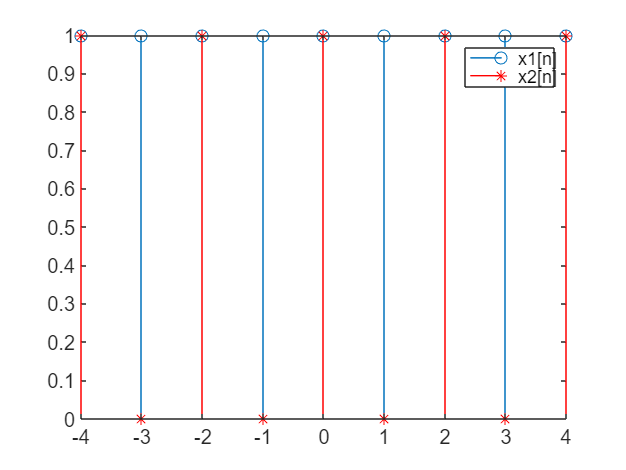

figure
stem(N,x1),hold on,stem(N,x2,'r','*')
legend('x1[n]','x2[n]')

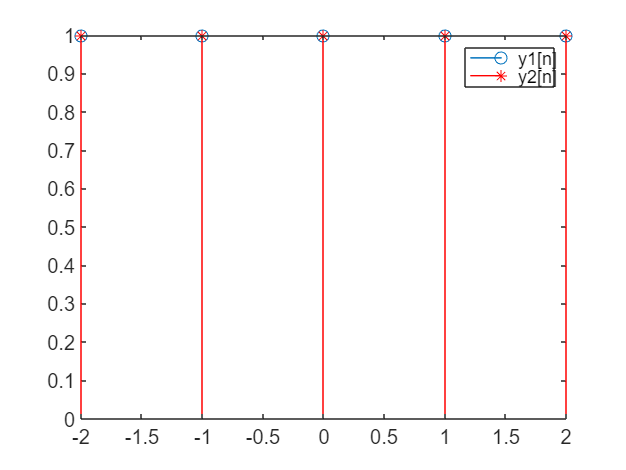

figure
stem(n,y1),hold on,stem(n,y2,'r','*')
legend('y1[n]','y2[n]')

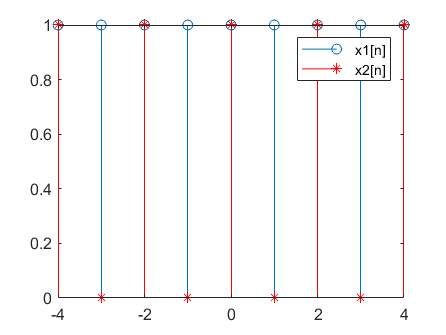

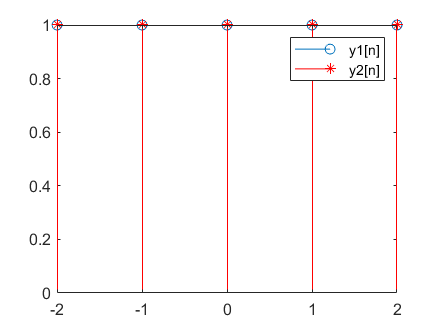

小结：可知输入不同，输出相同，则系统不可逆。

结论：y[n]=x[2n]线性、稳定；不可逆、时变、非因果。